# Cell OBJ Display

quickly plot the generated obj files

paths.project = "/Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project";
paths.analysis = fullfile(paths.project,"Lysosome Analysis");
paths.obj = fullfile(paths.project,"Lysosome Analysis","cell OBJ");

if exist(fullfile(paths.analysis,"cellT.mat"),"file")
    load(fullfile(paths.analysis,'cellT.mat')) %cellT
end

contents = dir(fullfile(paths.obj,"*manifold.obj"))

contents = 31×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


names = extractBefore(string({contents.name})','_manifold.obj');

names = 31×1 string array
    "TB1_AP02_EM"
    "TB1_AP13_EM"
    "TB1_AP14_EM"
    "TB1_AP16_EM"
    "TB1_AP31_EM"
    "TB1_AP34_EM"
    "TB1_AP36_EM"
    "TB1_AP37_EM"
    "TB1_AP38_EM"
    "TB1_AP40_EM"
    "TB1_AP44_EM"
    "TB1_AP51_EM"
    "TB1_AP70_RSL"
    "TB1_IMMCell09_CM_ry"
    "TB1_IMMcell08_CM_RKJ"
    "TB2_T1C-05_cw"
    "TB2_T1C-06_cw"
    "TB2_T2C-01_FR"
    "TB2_T2C-03_cw"
    "TB2_T2C-09_cw"
    "TB2_T2C-10_cw"
    "TB2_T2C-12_cw"
    "TB2_T2Cell03_CM_LES"
    "TB2_T3C-08_cw"
    "TB2_T3C-14_FR"
    "TB2_T3C-17_cw"
    "TB2_T3Cell07_cm_RSL"
    "TB2_T4C-01_cw"
    "TB2_TCdying-01_cw"
    "TB2_TCdying-02_cw"


mmfig

ans =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


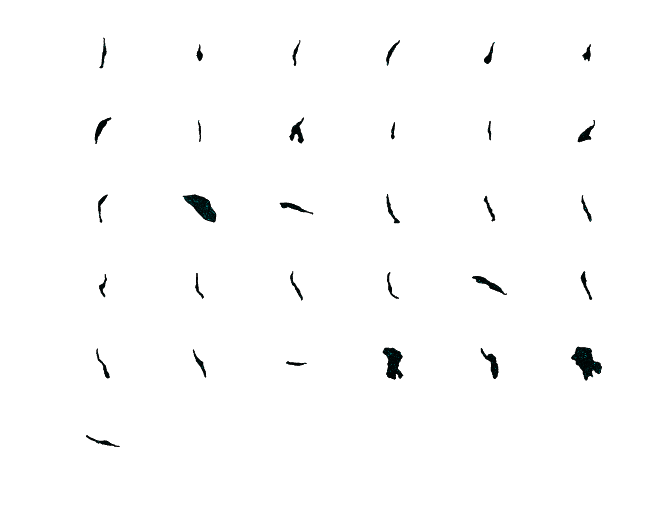

nfv = struct with fields:
       faces: [25665×3 double]
    vertices: [12829×3 double]


nfv = struct with fields:
       faces: [52735×3 double]
    vertices: [26360×3 double]


nfv = struct with fields:
       faces: [37383×3 double]
    vertices: [18691×3 double]


nfv = struct with fields:
       faces: [53008×3 double]
    vertices: [26503×3 double]


nfv = struct with fields:
       faces: [82820×3 double]
    vertices: [41404×3 double]


nfv = struct with fields:
       faces: [50591×3 double]
    vertices: [25288×3 double]


nfv = struct with fields:
       faces: [85476×3 double]
    vertices: [42730×3 double]


nfv = struct with fields:
       faces: [34028×3 double]
    vertices: [17015×3 double]


nfv = struct with fields:
       faces: [75593×3 double]
    vertices: [37786×3 double]


nfv = struct with fields:
       faces: [104067×3 double]
    vertices: [52027×3 double]


nfv = struct with fields:
       faces: [46063×3 double]
    vertices: [23019×3 double]


nfv = struct with fields:
       faces: [143534×3 double]
    vertices: [71747×3 double]


nfv = struct with fields:
       faces: [32919×3 double]
    vertices: [16458×3 double]


nfv = struct with fields:
       faces: [59771×3 double]
    vertices: [29876×3 double]


nfv = struct with fields:
       faces: [64142×3 double]
    vertices: [32068×3 double]


nfv = struct with fields:
       faces: [33422×3 double]
    vertices: [16710×3 double]


nfv = struct with fields:
       faces: [53453×3 double]
    vertices: [26725×3 double]


nfv = struct with fields:
       faces: [28010×3 double]
    vertices: [14004×3 double]


nfv = struct with fields:
       faces: [32255×3 double]
    vertices: [16123×3 double]


nfv = struct with fields:
       faces: [30815×3 double]
    vertices: [15408×3 double]


nfv = struct with fields:
       faces: [38387×3 double]
    vertices: [19196×3 double]


nfv = struct with fields:
       faces: [40746×3 double]
    vertices: [20374×3 double]


nfv = struct with fields:
       faces: [82595×3 double]
    vertices: [41287×3 double]


nfv = struct with fields:
       faces: [42998×3 double]
    vertices: [21497×3 double]


nfv = struct with fields:
       faces: [25829×3 double]
    vertices: [12910×3 double]


nfv = struct with fields:
       faces: [24728×3 double]
    vertices: [12361×3 double]


nfv = struct with fields:
       faces: [51047×3 double]
    vertices: [25522×3 double]


nfv = struct with fields:
       faces: [137275×3 double]
    vertices: [68616×3 double]


nfv = struct with fields:
       faces: [125901×3 double]
    vertices: [62943×3 double]


nfv = struct with fields:
       faces: [208964×3 double]
    vertices: [104451×3 double]


nfv = struct with fields:
       faces: [25452×3 double]
    vertices: [12722×3 double]


for n=1:height(contents)
    % cell_name = extractBefore(contents(1).name,'_manifold.obj')
    mesh = readSurfaceMesh(fullfile(paths.obj,contents(n).name));
    nfv = reducepatch(mesh.Faces,mesh.Vertices, 0.1);
    nexttile;
    hp = patch(nfv,...
        FaceColor='c',EdgeAlpha=0.1);
    axis vis3d equal
    axis off
end